# Relatório de Atividade - Análise em frequência e covariância

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Estimação e Identificação de Sistemas 21.2*

*24 de agosto de 2021*

Esse documento tem por objetivo descrever a caracterização de um modelo de um sistema linear, causal e invariante no tempo considerando um distúrbio aditivo desconhecido.

## Exercício A: Reproduza a Figura 2.7 e Figura 2.8 

Para o seguinte estudo, foi considerado um sistema invariante no tempo, linear e causal, isto é, cuja saída é unicamente representada por uma combinação de valores anteriores dos sinais de saída e entrada. Esse tipo de sistema pode ser modelado conforme:


$$y(t)=\int_{\tau=0}^{\infty}g(\tau)u(t-\tau)d\tau$$


nomeada resposta ao impulso. Considerando que os dados de entrada $u(t)$ e saída $y(t)$ são amostrados em $t_k=kT, k= 1,2,...$, pode-se reescrever $y(t)$ como:


$$y(kT)=\int_{\tau=0}^{\infty}g(\tau)u(kT-\tau)d\tau = \sum_{n=0}^\infty\int_{\tau=(k-1)T}^{kT}g(\tau)u(kT-\tau)d\tau =\sum_{n=0}^\infty g_T(n)u_{k-n}$$


para $u(t) = u_k $, $kT\leq t <(k+1)T$. Nesse estudo, considerou-se o período de amostragem $T=1$. Sabendo que $q^{-k}u(t) = u(t-k)$, é possível reescrever o modelo acima como:


$$y(t)=\sum_{k=0}^\infty g(k)q^{-k}u(t) = G(q)u(t)$$


Além disso, é possível considerar um distúrbio aditivo no modelo, tal como:


$$y(t) = \sum_{k=0}^\infty g(k)u(t-k) + v(t)$$


para $v(t)$ um sinal aleatório desconhecido.

Tendo em vista que o modelo do ruído não deve ser mais complexo do que a modelagem proposta para o sistema, é possível generalizar que:


$$v(t) = \sum_{k=0}^\infty h(k)e(t-k) = H(q)e(t)$$


para $e(t)$um ruído branco com distribuição $N(0,\lambda)$ e $h(t)$ um filtro qualquer para $h(0)=1$. Uma vez que $e(t)$ pode ser considerado um processo estocástico, é dado que $v(t)$ é a realização de um processo estocástico. Sendo assim, é adequada uma análise probabilística do modelo. A esperança e a covariância de $v(t)$ é dada por:


$$E[v(t)] = \sum_{k=0}^\infty h(k)E[e(t-k)] = 0$$



$$\begin{array}{rcl}
E[v(t)v(t-\tau)] = R_v(\tau) &=& \sum_{k=0}^\infty \sum_{s=0}^\infty h(k)h(s)E[e(t-k)e(t-\tau-s)]\\
&=& \sum_{k=0}^\infty \sum_{s=0}^\infty h(k)h(s)\delta(k-\tau-s)\lambda = \lambda \sum_{k=0}^\infty h(k)h(k-\tau)
\end{array}$$


já que $R_e(0) = \lambda$ e $R_e(\tau) = 0$ para $\tau\neq 0$. Como as expressões acima independem de $t$, $v(t)$ é considerado estacionário. 

Para quantificar o "peso" que cada componente de frequência $\omega=2\pi k/N$, para $N$ o número de amostra coletadas, na decomposição de $u(t)$, aplica-se a DFT (Transformada Discreta de Fourier):


$$U_N(\omega) = \frac{1}{\sqrt N}\sum_{t=1}^Nu(t)e^{-j\omega t}$$


Conforme a relação de Parseval, a energia do sinal $u(t)$ também pode ser decomposta conforme a magnitude das componentes em frequência $U_N(\omega)$:


$$\sum_{k=1}^N |U_N(2\pi k/N)|^2 = \sum_{t=1}^Nu^2(t)$$


Essa decomposição espectral é ilustrada na forma de um periodograma ($|U_N(\omega)|^2$). Entretanto, para sinais aleatórios não periódicos, a DFT retorna resultados erráticos. Isso se deve pelo fato da variância da estimativa em frequência não reduzir para zero com o aumento do número de amostras $N$[2]. Esse problema pode ser solucionado aplicando uma média móvel no sinal pós DFT. Se o conjunto de dados for grande, as estimativas individuais são obtidas de blocos de dados não sobrepostos. Caso $N$ seja pequeno, até metade de sobreposição do conjunto de dados permite a redução da variância da estimativa. Assintoticamente, o periodograma para $N\rightarrow\infty$ é equivalente a estimativa da potência de espectro de um sinal, a qual, para$s(t) = G(q)u(t) + H(q)v(t)$, é dada como:


$$\Phi_s(\omega) = \sum^\infty_{\tau=-\infty} R_s(\tau)e^{-j\tau\omega}$$


Para um processo $v(t)$ estocástico com covariância $R_v(\tau)=\lambda \sum_{k=0}^\infty h(k)h(k-\tau)$, tem-se que:


$$\begin{array}{rlc}
\Phi_v(\omega) &=\lambda \sum^\infty_{\tau=-\infty}  \sum_{k=\tau}^\infty h(k)h(k-\tau)e^{jk\omega} e^{j(k-\tau)\omega} \\
&= \lambda \sum_{s=0}^\infty h(s)e^{js\omega} \sum_{k=0}^\infty h(k)e^{-jk\omega} = \lambda|H(e^{j\omega})|^2
\end{array}$$


Observando a expressão acima, é evidente que o espectro só pode ser definido caso a função $H(q)$ seja conhecida.

Na Figura 1, estão ilustrados o periodograma $|V_N(\omega)|^2$ e espectro $\Phi_v(\omega)$ do sinal $v(t) = e(t)+0.5e(t-1)+1.5v(t-1)+0.7v(t-2)$ para $e(t)\sim N(0,1)$. 

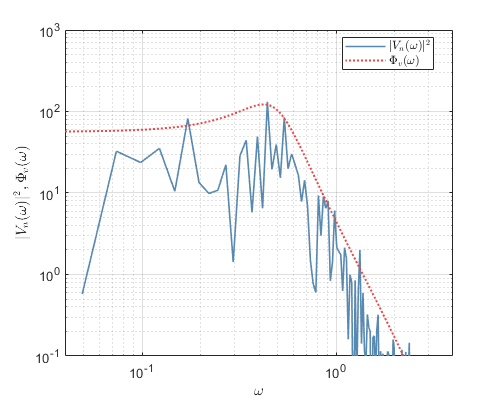

exA

**Figura 1**: Periodograma $|V_N(\omega)|^2$ e espectro $\Phi_v(\omega)$ do sinal $v(t)$. 

Conforme citado anteriormente, para sinais estocásticos não periódicos, o periodograma é errático. Dessa forma, é adequada a representação das componentes do espectro por $\Phi_v(\omega)$, a qual pode ser considerada como uma versão suavizada do sinal $|V_N(\omega)|^2$.

## Exercício B: Gere as realizações e funções de covariância do sinal distúrbio

Considere o modelo genérico do distúrbio $v(t)$ tal que:


$$v(t) + a_1v(t-1) + ... +a_nv(t-n) = c_0e(t)+c_1e(t-1) + ... c_ne(t-n)$$


para $e(t) \sim N(0,1)$, foram construídos os seguintes modelos para $v(t)$:

- $n=1$, $a_1=-0.9$, $c_0=1$, $c_1=0$

- $n=1$, $a_1=0.9$, $c_0=1$, $c_1=0$

- $n=2
$, $a_1=-0.5
$, $a_2=0.7$, $c_0=1$, $c_1=0.5
$, $c_2=2$

- Semelhante a (3), mas $e(t)$ distribuído como $P(e(t))=0)=0.98$, $P(e(t)=\sqrt{50})=0.01
$ e $P(e(t)=-\sqrt{50})=0.01
$

As realizações dos processos, isto é, o valor de $v(t)$ para $N = 200$ amostras está ilustrado na Figura 2.

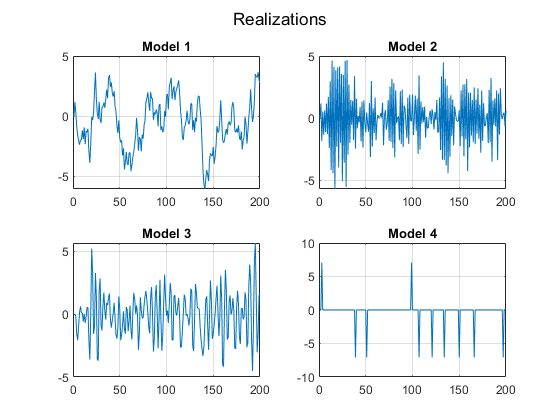

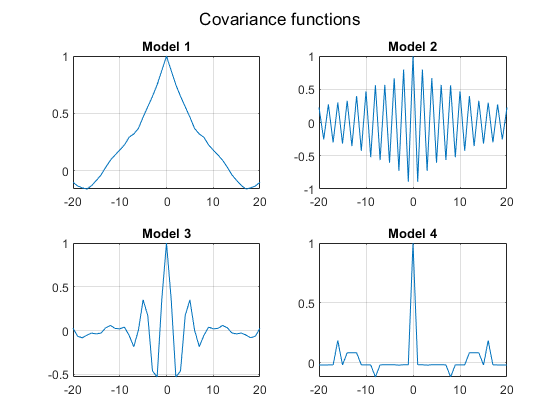

exB

**Figura 2: **Realizações e funções de covariância para o sinal $v(t)$resultante dos quatro modelos propostos.

A diferença entre os gráficos apresentados na Figura 2 e na literatura referenciada é justificada pela semente da função aleatória, a qual é responsável por gerar o ruído branco $e(t)$. 

## Exercício C: Obtenha as expressões de variância e covariância do processo ARMA

Um processo estocástico estacionário $v(t)$ que possuí um espectro racional $\Phi_v(\omega)$ pode ser representado como $v(t)=H(q)e(t)$ para $e(t)$um ruído branco de média nula e covariância $\lambda$. A função de transferência $H(q)$ pode ser representada como:

$H(q)=\frac{C(q)}{A(q)}$, para $C(q) = 1+c_1q^{-1} + ... c_{n_c}q^{-n_c}$ e $A(q) = 1+a_1q^{-1} + ... a_{n_a}q^{-n_a}$

Logo, analogamente ao Exercício B, o modelo genérico do distúrbio $v(t)$ é:


$$v(t) + a_1v(t-1) + ... +a_{n_a}v(t-n_a) = e(t)+c_1e(t-1) + ... c_{n_c}e(t-n_c)$$


Se $n_c=0$, a expressão acima é transformada em um modelo autorregressivo (AR), ou seja:


$$v(t) + a_1v(t-1) + ... +a_{n_a}v(t-n_a) = e(t)$$


Caso $n_a=0$, encontra-se um modelo de média móvel (MA), isto é:


$$v(t)  = e(t)+c_1e(t-1) + ... c_{n_c}e(t-n_c)$$


Sendo assim, essa modelagem do distúrbio é nomeada ARMA. A notação desse tipo de processo é dada por $(n_a,n_c)$. 

Considerando o processo ARMA(2,2), ou seja, $n_a=n_c=2$,  um processo $y(t)$ é modelado conforme a expressão abaixo:


$$y(t)=-a_1y(t-1)-a_2y(t-2)+e(t)+c_1e(t-1)+c_2e(t-2)
$$


Pode-se substituir $y(k)=y_k$ e $e(k)=e_k$ para facilitar a notação. Multiplicando a expressão acima por $y_t$, $y_{t-1}$, $y_{t-2}$, $e_{t}$, $e_{t-1}$ e $e_{t-2}$ e aplicando o operador de expectativa matemática (esperança), obtém-se as seguintes covariâncias:


$$\begin{array}{rcl}
R_{ey}(0)&=&E(e_ty_t)&=&-a_1E(e_ty_{t-1})-a_2E(e_ty_{t-2})+E(e_te__t)+c_1E(e_te_{t-1})+c_2E(e_te_{t-2})\\
R_{ey}(1)&=&E(e_{t-1}y_t)&=&-a_1E(e_{t-1}y_{t-1})-a_2E(e_{t-1}y_{t-2})+E(e_{t-1}e__t)+c_1E(e_{t-1}e_{t-1})+c_2E(e_{t-1}e_{t-2})\\
R_{ey}(2)&=&E(e_{t-2}y_t)&=&-a_1E(e_{t-2}y_{t-1})-a_2E(e_{t-2}y_{t-2})+E(e_{t-2}e__t)+c_1E(e_{t-2}e_{t-1})+c_2E(e_{t-2}e_{t-2})\\
R_{y}(0)&=&E(y_ty_t)&=&-a_1E(y_ty_{t-1})-a_2E(y_ty_{t-2})+E(y_te__t)+c_1E(y_te_{t-1})+c_2E(y_te_{t-2})\\
R_{y}(1)&=&E(y_{t-1}y_t)&=&-a_1E(y_{t-1}y_{t-1})-a_2E(y_{t-1}y_{t-2})+E(y_{t-1}e__t)+c_1E(y_{t-1}e_{t-1})+c_2E(y_{t-1}e_{t-2})\\
R_{y}(2)&=&E(y_{t-2}y_t)&=&-a_1E(y_{t-2}y_{t-1})-a_2E(y_{t-2}y_{t-2})+E(y_{t-2}e__t)+c_1E(y_{t-2}e_{t-1})+c_2E(y_{t-2}e_{t-2})\\

\end{array}$$


Considerando que $E(e_iy_k)=0, \forall i>k$ e que o erro $e(t)$ é um ruído gaussiano, isto é, $E(e_ie_k)=0, \forall i\neq k$ e $E(e_ie_k)=\lambda$ para $i=k$, tem-se que:


$$\begin{array}{rcl}
R_{ey}(0)&=&E(e_ty_t)&=&E(e_te__t)\\
R_{ey}(1)&=&E(e_{t-1}y_t)&=&-a_1E(e_{t-1}y_{t-1})+c_1E(e_{t-1}e_{t-1})&=&-a_1R_{ey}(0)+c_1E(e_te__t)\\
R_{ey}(2)&=&E(e_{t-2}y_t)&=&-a_1E(e_{t-2}y_{t-1})-a_2E(e_{t-2}y_{t-2})+c_2E(e_{t-2}e_{t-2})&=&-a_1R_{ey}(1)-a_2R_{ey}(0)+c_2E(e_{t}e_{t})\\
R_{y}(0)&=&E(y_ty_t)&=&-a_1E(y_ty_{t-1})-a_2E(y_ty_{t-2})+E(y_te__t)+c_1E(y_te_{t-1})+c_2E(y_te_{t-2})&=&-a_1R_{y}(1)-a_2R_{y}(2)+R_{ey}(0)+c_1R_{ey}(1)+c_2R_{ey}(2)\\
R_{y}(1)&=&E(y_{t-1}y_t)&=&-a_1E(y_{t-1}y_{t-1})-a_2E(y_{t-1}y_{t-2})+c_1E(y_{t-1}e_{t-1})+c_2E(y_{t-1}e_{t-2})&=&-a_1R_{y}(0)-a_2R_{y}(1)+c_1R_{ey}(0)+c_2R_{ey}(1)\\
R_{y}(2)&=&E(y_{t-2}y_t)&=&-a_1E(y_{t-2}y_{t-1})-a_2E(y_{t-2}y_{t-2})+c_2E(y_{t-2}e_{t-2})&=&-a_1R_{y}(1)-a_2R_{y}(0)+c_2R_{ey}(0)\\

\end{array}$$


Substituindo os valores nas equações de $R_{ey}(\tau)
$ para $\tau=0,1,2$, obtém-se:


$$\begin{array}{rcl}
R_{ey}(0)&=&E(e_te__t) = \lambda\\
R_{ey}(1)&=&-a_1R_{ey}(0)+c_1E(e_te__t) =  \lambda(-a_1+c_1)\\
R_{ey}(2)&=&-a_1R_{ey}(1)-a_2R_{ey}(0)+c_2E(e_{t}e_{t})=\lambda\big[(a_1)^2-a_1c_1-a_2+c_2\big]
\end{array}$$


Em seguida, calculando $R_{y}(\tau)
$ para $\tau=0,1,2$, obtém-se:


$$\begin{array}{rcl}
R_{y}(0)&=&\gamma_0&=&-a_1\gamma_1-a_2\gamma_2+k_0\\
R_{y}(1)&=&\gamma_1&=&-a_1\gamma_0-a_2\gamma_1+k_1\\
R_{y}(2)&=&\gamma_2&=&-a_1\gamma_1-a_2\gamma_0+k_2\\
\end{array}$$


para $k_0 = \lambda[1+c_1(-a_1+c_1)+c_2\big((a_1)^2-a_1c_1-a_2+c_2\big)]$, $k_1= \lambda[c_1+c_2(-a_1+c_1)]$ e $k_2 = \lambda c_2$. Isolando $\gamma_1$ na equação de $R_y(1)$, tem-se que $\gamma_1=\frac{-a_1\gamma_0+k_1}{(1+a_2)}$. Substituindo na equação de $\gamma_2$, tem-se:


$$\gamma_2 = -a_1\bigg[\frac{-a_1\gamma_0+k_1}{(1+a_2)}\bigg]-a_2\gamma_0+k_2 = 
\frac{(a_1)^2\gamma_0-a_1k_1-a_2\gamma_0+k_2-(a_2)^2\gamma_0+a_2k_2}{(1+a_2)}$$


Logo, finalmente substituindo em $\gamma_0$, tem-se que:


$$\begin{array}{rlc}
\gamma_0&=&-a_1\bigg[\frac{-a_1\gamma_0+k_1}{(1+a_2)}\bigg]-a_2\bigg[\frac{(a_1)^2\gamma_0-a_1k_1-a_2\gamma_0+k_2-(a_2)^2\gamma_0+a_2k_2}{(1+a_2)}\bigg]+k_0\\
&=&\frac{(a_1)^2\gamma_0-a_1k_1-(a_1)^2a_2\gamma_0+a_1a_2k_1+(a_2)^2\gamma_0-a_2k_2+(a_2)^3\gamma_0-(a_2)^2k_2+k_0+a_2k_0}{(1+a_2)}
\end{array}$$


Isolando $\gamma_0$, obtém-se que:


$$\begin{array}{rlc}
\gamma_0&=&\frac{-a_1k_1+a_1a_2k_1-a_2k_2-(a_2)^2k_2+k_0+a_2k_0}{1+a_2-(a_1)^2+(a_1)^2a_2-(a_2)^2-(a_2)^3}
\end{array}$$


Fatorando o denominador e substituindo as constantes $k_0$, $k_1$ e $k_2$ da expressão de $\gamma_0$, é encontrada que a variância de $y(t)$ é:


$$\gamma_0 = \frac{(1+a_2)\big[1+(c_1)^2+(c_2)^2\big]-2a_1c_1(1+c_2)-2c_2\big[a_2-(a_1)^2+(a_2)^2\big]}{(1-a_2)(1-a_1+a_2)(1+a_1+a_2)}$$


## Exercício D: Gerar um texto em vernáculo e em formato de artigo conforme o texto "Stochastic Model"

Um distúrbio genérico aplicado sobre um sistema pode ser caracterizado por um processo aleatório, cujo valor não é conhecido previamente. Entretanto, é possível produzir predições sobre esse valor conforme a natureza probabilística de um processo estocástico. Seja $ e(t_k)$ uma série temporal de variáveis aleatórias independentes, isto é, um ruído branco, tem-se que:


$$w(t) + d_1w(t-T)+...+d_nw(t-nT)=c_0e(t)+c_1e(t-T)+...+c_ne(t-nT)$$


para $e(t)\in N(0,\lambda)$. O processo $w(t)$ é determinado uma realização de um processo estocástico, isto é, uma série de variáveis estocásticas com distribuição característica. O modelo acima descrito é denominado ARMA, e pode ser descrito como uma função racional $H(q)$ tal que:


$$H(q)=\frac{C(q)}{D(q)}$$


Como o valor de $e(t)$ não depende de $t$, assim também será para $w(t)$. Logo, pode-se nomear $w(t)$ como processo estocástico estacionário. 

A expectativa matemática (ou esperança) do sinal $w(t)$ é descrita como $m_w=Ew(t)$. Por sua vez, a covariância é determinada como $R_w(t,s) = E(w(t)-m_w(t))(w(s)-m_w(s))$. Já que $w(t)$ é um processo estarionário, a covariância $R_w(t,s)$ depende unicamente de $\tau = t-s$.

A decomposição de um sinal em uma soma de senoides de determinada frequência é essencial para a caracterização de um distúrbio. Essa decomposição pode ser encontrada pela transformada de Fourier ($W_N(\omega)$), e o quadrado da magnitude das componentes de frequência presentes na decomposição do sinal é nomeada espectro ($\Phi_w(\omega)$). A potência de um sinal é então determinada por:


$$\int_{\omega_1}^_{\omega_2}\Phi_w(\omega)d\omega$$


para $\omega_1<\omega_2$. Entretanto, esse conceito é modificado conforme os sinais possuem:

- Energia finita: o espectro é definido como $\Phi_w(\omega) =|W_N(\omega)|^2$;

- Energia infinita: o espectro é calculado para um sinal $w^{'}(t)$ referente ao truncamento do sinal original $w(t)$, posteriormente normalizado e levado ao infinito, ou seja $\Phi_w(\omega) =\lim_{N\rightarrow\infty}\frac{1}{N}|W^{'}_N(\omega)|^2$;

- ou são realizações de um processo estocástico: o espectro é definido por $\Phi_w(\omega) =\lim_{N\rightarrow\infty}E\bigg[\frac{1}{N}|W^{'}_N(\omega)|^2\bigg]$.

Por sua vez, a dependência de dois sinais $u(t)$ e $y(t)$ pode ser inferida pelo espectro cruzado, isto é, $\Phi_{yu}(\omega)$. Se $\Phi_{yu}(\omega)=0$, esses sinais são descorrelacionados. Para sinais $y(t)$ e $u(t)$ estocásticos, $\Phi_{yu}(\omega)$ equivale à transformada de fourier da função de covariância $R_{uy}(\tau)$. 

Considere três sinais $y(t)$, $u(t)$ e $w(t)$ associados conforme a seguinte expressão:


$$y(t) = G(p)u(t)+w(t)$$


 para $p$ o operador diferencial, e $u(t)$ e $w(t)$ sinais independentes. Conforme a transformada contínua de Fourier, as componentes em frequência desse sinal são relacionadas por:


$$Y(\omega) = G(j\omega)U(\omega)+W(\omega)$$


Tomando o valor absoluto quadrado de cada termo a direita da igualdade e normalizando pelo intervalo de $N$ amostras, tem-se, a partir do conceito de espectro anteriormente definido:


$$\Phi_{y}(\omega) = G(j\omega)^2\Phi_{u}(\omega)+\Phi_{w}(\omega)$$


uma vez que $\Phi_{wu}(\omega)=0$. Analogamente, para o tempo discreto, tem-se que $Y(\omega) = G(e^{j\omega t})U(\omega)+W(\omega)$.

## **Referências bibliográficas**

[1] L. LJUNG. **System Identification: Theory for the User**. Pearson, 1998. 2nd edition, ISBN 9788131744956.

[2] **PSD Estimation Using the DFT**. (Disponível em: [http://www.ee.iitm.ac.in/~skrishna/ee471/dft_lab2.pdf](http://www.ee.iitm.ac.in/~skrishna/ee471/dft_lab2.pdfhttp://www.ee.iitm.ac.in/~skrishna/ee471/dft_lab2.pdf))